システム同定?

seri = serialport("COM9", 57600, "ByteOrder", "big-endian", "Timeout", 0.1);

SAMPLING_TIME = 0.025;  % 1サンプルの頻度は25[ms]程度であることを予備実験で確認
INPUT_VOLTAGE = 0;
STEP_TIME = 2;
END_TIME = 5;

Kp = 3;

%初期値取得
for i = 1 : 100
    write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    sh2pc(i) = sci_read_with_decode_using_checksum(seri);
end

% BASE = double(0x30d40); %20万
% GOAL_ANGLE = 30/360;
BASE = double(0x3FFFF);
GOAL_ANGLE = pi/6;

for i = 1 : (END_TIME / SAMPLING_TIME)
    %tic;
    if (i >= STEP_TIME / SAMPLING_TIME)
        
        rad = baseangle2rad(sh2pc2(i-1).BaseAngle);
        disp("rad[deg]=");
        disp(rad*360/(2*pi));        
        
        INPUT_VOLTAGE = double(Kp*(GOAL_ANGLE - rad));
        
        if abs(INPUT_VOLTAGE) > 1
            INPUT_VOLTAGE = double(sign(INPUT_VOLTAGE));
        end
        
        write(seri, typecast(swapbytes(INPUT_VOLTAGE), 'uint8'), 'uint8');
        
    else
        write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    end
    
    sh2pc2(i) = sci_read_with_decode_using_checksum(seri);
    
    volt(i)=INPUT_VOLTAGE;
    angle(i)=double(sh2pc2(i).BaseAngle)/BASE;
    
    disp(i);
    disp(INPUT_VOLTAGE);
    disp(double(sh2pc2(i).BaseAngle)/BASE)
    %pause(SAMPLING_TIME - toc);
end
%write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');

write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
pause(0.5);
clear s;
clear sh2pc sh2pc2;
clear volts angle;

plot(angle*360);

sh2pc2table=struct2table(sh2pc2);
t = sh2pc2table.TMStamp - sh2pc2table.TMStamp(1);
y = double(sh2pc2table.BaseAngle)*360/BASE;
plot(t, y);

%% 変数を同定
Amax = double(max(sh2pc2table.BaseAngle))*360/BASE - 30;%[deg]
rc_d = 30;
rc = pi/6;%[rad]
%Tp = 0.178;
Tp = sh2pc2table.TMStamp( sh2pc2table.BaseAngle==max(sh2pc2table.BaseAngle) ) - sh2pc2table.TMStamp(80);
Tp = double(Tp)/1000;
% Tp2 = 19.5e-3;
% Kpp = 0.00012892;
xi1 = -(1/Tp)*log(Amax/rc_d);
% xi1 = -(1/Tp2)*log(Amax/rc_d);

omega_n1 = sqrt( (pi/Tp)^2 + xi1^2 );
% omega_n1 = sqrt( (pi/Tp2)^2 + xi1^2 );
zeta1 = xi1 / omega_n1;

a = 2*zeta1*omega_n1;
b = omega_n1^2/Kp;
% b = omega_n1^2/Kpp;

t_sim = 0:0.01:2;
theta1_sim = rc*step(omega_n1^2, [1 2*zeta1*omega_n1 omega_n1^2], t_sim);

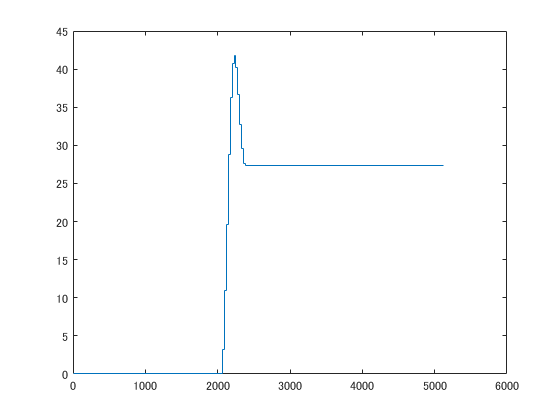

figure(6)
stairs(double( t(80:120)-t(80) )/1000, y(80:120));

%plot(double( t(80:200)-t(80) )/100, y(80:200));
hold on
plot(t_sim, theta1_sim*180/pi, 'r');
hold off

stairs(double(sh2pc2table.TMStamp(80:150) - sh2pc2table.TMStamp(80))/1000, double(sh2pc2table.BaseAngle(80:150))*2*pi/BASE);
hold on
plot(t_sim, theta1_sim, 'r');
hold off

%%ArmAngleの特性を見る
pause(5);
for i = 1 : 2000
    disp(i);
    write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    sh2pc3(i) = sci_read_with_decode_using_checksum(seri);
end

init_arm = 809; %sh2pc(1).ArmAngle

sh2pc3Table=struct2table(sh2pc3);
t2 = sh2pc3Table.TMStamp - sh2pc3Table.TMStamp(1);
y2 = (double(sh2pc3Table.ArmAngle)-809)*360/1024;
plot(sh2pc3Table.ArmAngle);
plot(double(t2)/1000, y2);
plot(y2);
hold on
plot(locs, y2(locs), 'ko');
hold off

%棒の角度の局所最大値を抽出
[pks, locs]=findpeaks(y2);
%局所最大値のインデックス
Xidx = [865 929 995 1058 1123 1184 1249 1314 1376 1442 1506];
stairs(double(t2(865:1510)-t2(865))/1000, y2(865:1510));

%周期の平均
T = double(sum( diff( t2(Xidx) ) ))/ (length(Xidx)-1);
T = T/1000;
%減衰率の平均
for l = 1:(length(Xidx)-3)
    lambdas(l) = y2(Xidx(l+1))/y2(Xidx(l)); 
end
lambda = mean(lambdas);

%アームのパラメータ同定
xi2 = -(1/T)*log(lambda);
omega_n2 = sqrt( ((2*pi)/T)^2 + xi2^2 );
zeta2 = xi2/omega_n2;

%m2 = 0.1;
g = 9.81;
% l2 = 0.115;

J2b = m2*g*l2/(omega_n2^2);
J2 = J2b - m2*l2^2;
c2 = 2*J2b*zeta2*omega_n2;

%アームのシミュレーションプロット
t_sim2 = 0:0.01:10;
omega_d2 = omega_n2*sqrt(1-zeta2^2);
phi2_sim = exp(-zeta2*omega_n2*t_sim2).*(cos(omega_d2*t_sim2)+zeta2/sqrt(1-zeta2^2)*sin(omega_d2*t_sim2))*( y2(Xidx(1))*pi/180 );

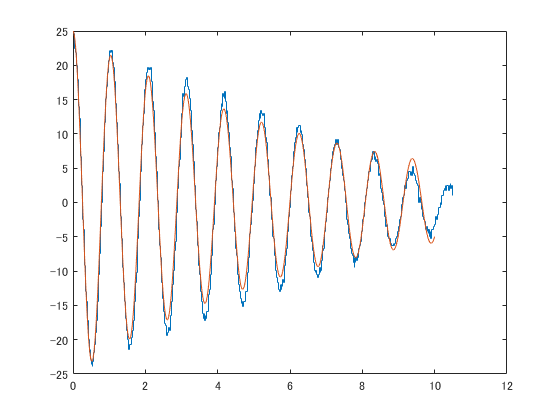

stairs(double(t2(865:1510)-t2(865))/1000, y2(865:1510));
hold on
plot(t_sim2, phi2_sim*180/pi);
hold off

% t = sh2pc3Table.TMStamp - sh2pc3Table.TMStamp(1);
% y = double(sh2pc2table.BaseAngle)*360/BASE;
% plot(t, y);
